## Brug af `eulsys` og `rk4system`

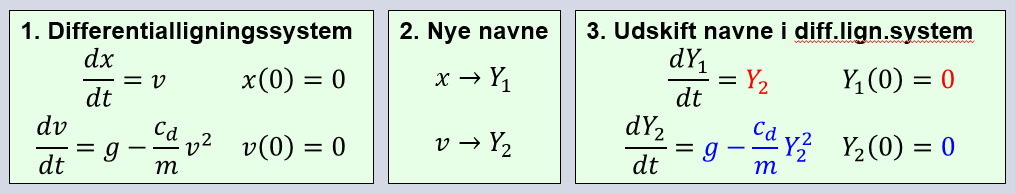

**4. Benyt resultater i **`eulsys`** og **`rk4system`

clear
g = 9.81; m = 68.1; cd = 0.25;
dYdt = @(t,Y) [Y(2), g-cd/m*Y(2)^2];
Y0 = [0 0];
tidsinterval = [0 12];
h = 2;
[t,Y] = eulsys(dYdt,tidsinterval,Y0,h)

t =      0
     2
     4
     6
     8
    10
    12


Y =          0         0
         0   19.6200
   39.2400   36.4137
  112.0674   46.2983
  204.6640   50.1802
  305.0244   51.3123
  407.6490   51.6008


x = Y(:,1); v = Y(:,2);
disp(table(t,x,v))

    t       x         v   
    __    ______    ______
     0         0         0
     2         0     19.62
     4     39.24    36.414
     6    112.07    46.298
     8    204.66     50.18
    10    305.02    51.312
    12    407.65    51.601
